**Plotagem de gráficos Sistema suspensão ativa**

clear, clc

plantaGeralW1 = readtable("C:\Users\luiza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\12V-crtl-final-susp-16-02-2024 13-09.csv");
plantaGeralW2 = readtable("C:\Users\luiza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\10V-crtl-final-susp-16-02-2024 13-50.csv");
plantaGeralW3 = readtable("C:\Users\luiza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\9V-crtl-final-susp-16-02-2024 13-52.csv");
plantaGeralW4 = readtable("C:\Users\luiza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\6V-crtl-final-susp-16-02-2024 13-55.csv");

% plantaGeralW1 = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\12V-crtl-final-susp-16-02-2024 13-09.csv");
% plantaGeralW2 = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\10V-crtl-final-susp-16-02-2024 13-50.csv");
% plantaGeralW3 = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\9V-crtl-final-susp-16-02-2024 13-52.csv");
% plantaGeralW4 = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\Dados validação final\6V-crtl-final-susp-16-02-2024 13-55.csv");

Ts = 19e-3;

**Gráficos Dist\'urbio W1**

w1FlagNoU = plantaGeralW1.CONTROLLER_FLAG == 0;
w1FlagU   = plantaGeralW1.CONTROLLER_FLAG > 0;

aceleracaoW1NoU = plantaGeralW1.Sprung_acceleration_x(w1FlagNoU, :);
aceleracaoW1NoU = aceleracaoW1NoU(200:end, :);

aceleracaoW1 = plantaGeralW1.Sprung_acceleration_x(w1FlagU, :);
aceleracaoW1 = aceleracaoW1(1400:end, :);

[NoUW1N, ~] = size(aceleracaoW1NoU);
tW1NoU = linspace(0, NoUW1N, NoUW1N)';

[W1N, ~] = size(aceleracaoW1);
tW1 = linspace(0, W1N, W1N)';

seriesW1AceleracaoNoU = [Ts*tW1NoU, aceleracaoW1NoU];
seriesW1Aceleracao =    [Ts*tW1, aceleracaoW1];

% Valor RMS da aceleração vertical
rmsW1NoU = rms(aceleracaoW1NoU)

rmsW1NoU =           2.78015490578754


rmsW1    = rms(aceleracaoW1)

rmsW1 =            2.4556579950913



maxW1NoU = max(aceleracaoW1NoU)

maxW1NoU =                       7.58


maxW1    = max(aceleracaoW1)

maxW1 =                       7.84



(maxW1 - maxW1NoU)/maxW1NoU * 100

ans =           3.43007915567282



minW1NoU = min(aceleracaoW1NoU)

minW1NoU =                      -7.49


minW1    = min(aceleracaoW1)

minW1 =                      -7.03



(minW1 - minW1NoU)/minW1NoU * 100

ans =           -6.1415220293725



% COLOCAR ENTRADA THETA

disp("Aceleração RMS sem U | Aceleração RMS com U | Variação(%)")

Aceleração RMS sem U | Aceleração RMS com U | Variação(%)


disp(rmsW1NoU + " | " + rmsW1 + " | " + (rmsW1 - rmsW1NoU)/rmsW1NoU * 100)

2.7802 | 2.4557 | -11.6719


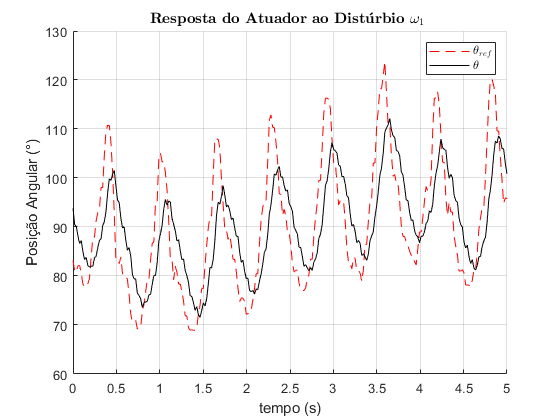


W1U = plantaGeralW1.U(w1FlagU, :);
W1U = W1U(1400:end, :);
W1Theta = plantaGeralW1.SL_position(w1FlagU, :);
W1Theta = W1Theta(1400:end, :);

figure
hold on
title("\textbf{Resposta do Atuador ao Dist\'urbio $\omega_{1}$ }", 'Interpreter', 'latex');
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tW1*Ts, W1U,'r--');
plot(tW1*Ts, W1Theta,'k');
legend("$\theta_{ref}$", "$\theta$", 'Interpreter', 'latex')
axis([0 5 60 130])
grid
hold off

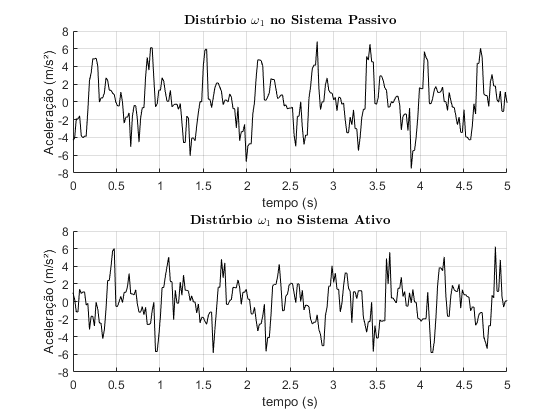



figure
subplot(211)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW1NoU*Ts, aceleracaoW1NoU,'k');
title("\textbf{Dist\'urbio $\omega_{1}$ no Sistema Passivo}", 'Interpreter', 'latex');
axis([0 5 -8 8])
yticks([-8:2:8])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

subplot(212)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW1*Ts, aceleracaoW1,'k');
title("\textbf{Dist\'urbio $\omega_{1}$ no Sistema Ativo}", 'Interpreter', 'latex');
axis([0 5 -8 8])
yticks([-8:2:8])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

**Gráficos Dist\'urbio W2**

W2FlagNoU = plantaGeralW2.CONTROLLER_FLAG == 0;
W2FlagU   = plantaGeralW2.CONTROLLER_FLAG > 0;

aceleracaoW2NoU = plantaGeralW2.Sprung_acceleration_x(W2FlagNoU, :);
aceleracaoW2NoU = aceleracaoW2NoU(200:end, :);

aceleracaoW2 = plantaGeralW2.Sprung_acceleration_x(W2FlagU, :);
aceleracaoW2 = aceleracaoW2(200:end, :);

[NoUW2N, ~] = size(aceleracaoW2NoU);
tW2NoU = linspace(0, NoUW2N, NoUW2N)';

[W2N, ~] = size(aceleracaoW2);
tW2 = linspace(0, W2N, W2N)';

seriesW2AceleracaoNoU = [Ts*tW2NoU, aceleracaoW2NoU];
seriesW2Aceleracao =    [Ts*tW2, aceleracaoW2];

% Valor RMS da aceleração vertical
rmsW2NoU = rms(aceleracaoW2NoU)

rmsW2NoU =           1.91517361715457


rmsW2    = rms(aceleracaoW2)

rmsW2 =           1.59870527657665



maxW2NoU = max(aceleracaoW2NoU)

maxW2NoU =                        4.5


maxW2    = max(aceleracaoW2)

maxW2 =                       4.16



(maxW2 - maxW2NoU)/maxW2NoU * 100

ans =          -7.55555555555555



minW2NoU = min(aceleracaoW2NoU)

minW2NoU =                      -5.71


minW2    = min(aceleracaoW2)

minW2 =                      -5.11



(minW2 - minW2NoU)/minW2NoU * 100

ans =           -10.507880910683



disp("Aceleração RMS sem U | Aceleração RMS com U | Variação(%)")

Aceleração RMS sem U | Aceleração RMS com U | Variação(%)


disp(rmsW2NoU + " | " + rmsW2 + " | " + (rmsW2 - rmsW2NoU)/rmsW2NoU * 100)

1.9152 | 1.5987 | -16.5243


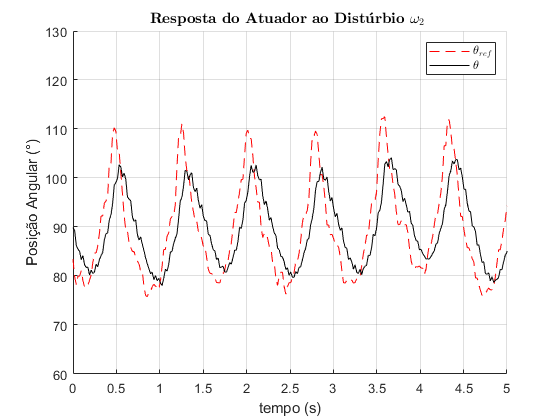


W2U = plantaGeralW2.U(W2FlagU, :);
W2U = W2U(200:end, :);
W2Theta = plantaGeralW2.SL_position(W2FlagU, :);
W2Theta = W2Theta(200:end, :);

figure
hold on
title("\textbf{Resposta do Atuador ao Dist\'urbio $\omega_{2}$ }", 'Interpreter', 'latex');
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tW2*Ts, W2U,'r--');
plot(tW2*Ts, W2Theta,'k');
legend("$\theta_{ref}$", "$\theta$", 'Interpreter', 'latex')
axis([0 5 60 130])
grid
hold off

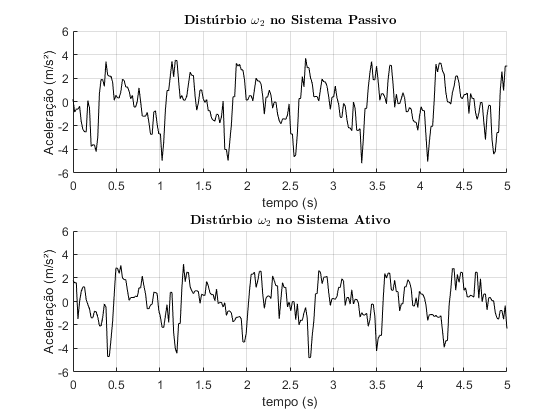


figure
subplot(211)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW2NoU*Ts, aceleracaoW2NoU,'k');
title("\textbf{Dist\'urbio $\omega_{2}$ no Sistema Passivo}", 'Interpreter', 'latex');
axis([0 5 -6 6])
yticks([-8:2:8])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

subplot(212)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW2*Ts, aceleracaoW2,'k');
title("\textbf{Dist\'urbio $\omega_{2}$ no Sistema Ativo}", 'Interpreter', 'latex');
axis([0 5 -6 6])
yticks([-8:2:8])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

**Gráficos Dist\'urbio W3**

W3FlagNoU = plantaGeralW3.CONTROLLER_FLAG == 0;
W3FlagU   = plantaGeralW3.CONTROLLER_FLAG > 0;

aceleracaoW3NoU = plantaGeralW3.Sprung_acceleration_x(W3FlagNoU, :);
aceleracaoW3NoU = aceleracaoW3NoU(200:end, :);

aceleracaoW3 = plantaGeralW3.Sprung_acceleration_x(W3FlagU, :);
aceleracaoW3 = aceleracaoW3(200:end, :);

[NoUW3N, ~] = size(aceleracaoW3NoU);
tW3NoU = linspace(0, NoUW3N, NoUW3N)';

[W3N, ~] = size(aceleracaoW3);
tW3 = linspace(0, W3N, W3N)';

seriesW3AceleracaoNoU = [Ts*tW3NoU, aceleracaoW3NoU];
seriesW3Aceleracao =    [Ts*tW3, aceleracaoW3];

% Valor RMS da aceleração vertical
rmsW3NoU = rms(aceleracaoW3NoU)

rmsW3NoU =            1.4677851500376


rmsW3    = rms(aceleracaoW3)

rmsW3 =           1.38627526817069



maxW3NoU = max(aceleracaoW3NoU)

maxW3NoU =                       3.24


maxW3    = max(aceleracaoW3)

maxW3 =                       3.58



(maxW3 - maxW3NoU)/maxW3NoU * 100

ans =           10.4938271604938



minW3NoU = min(aceleracaoW3NoU)

minW3NoU =     -5


minW3    = min(aceleracaoW3)

minW3 =                      -4.53



(minW3 - minW3NoU)/minW3NoU * 100

ans =                       -9.4



disp("Aceleração RMS sem U | Aceleração RMS com U | Variação(%)")

Aceleração RMS sem U | Aceleração RMS com U | Variação(%)


disp(rmsW3NoU + " | " + rmsW3 + " | " + (rmsW3 - rmsW3NoU)/rmsW3NoU * 100)

1.4678 | 1.3863 | -5.5533


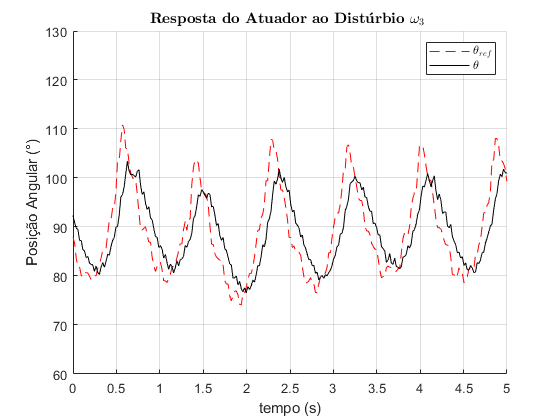


W3U = plantaGeralW3.U(W3FlagU, :);
W3U = W3U(200:end, :);
W3Theta = plantaGeralW3.SL_position(W3FlagU, :);
W3Theta = W3Theta(200:end, :);

figure
hold on
title("\textbf{Resposta do Atuador ao Dist\'urbio $\omega_{3}$ }", 'Interpreter', 'latex');
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tW3*Ts, W3U,'r--');
plot(tW3*Ts, W3Theta,'k');
legend("$\theta_{ref}$", "$\theta$", 'Interpreter', 'latex')
axis([0 5 60 130])
grid
hold off

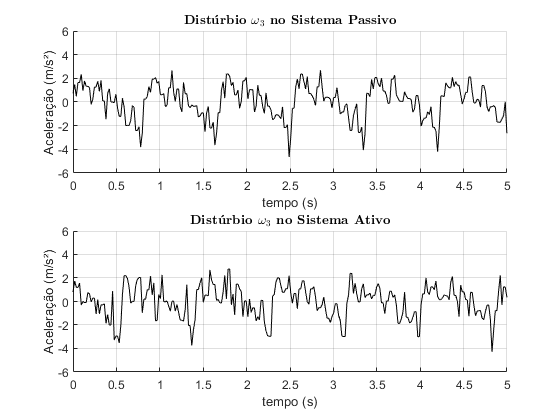


figure
subplot(211)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW3NoU*Ts, aceleracaoW3NoU,'k');
title("\textbf{Dist\'urbio $\omega_{3}$ no Sistema Passivo}", 'Interpreter', 'latex');
axis([0 5 -6 6])
yticks([-8:2:8])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

subplot(212)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW3*Ts, aceleracaoW3,'k');
title("\textbf{Dist\'urbio $\omega_{3}$ no Sistema Ativo}", 'Interpreter', 'latex');
axis([0 5 -6 6])
yticks([-8:2:8])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

**Gráficos Dist\'urbio W4**

W4FlagNoU = plantaGeralW4.CONTROLLER_FLAG == 0;
W4FlagU   = plantaGeralW4.CONTROLLER_FLAG > 0;

aceleracaoW4NoU = plantaGeralW4.Sprung_acceleration_x(W4FlagNoU, :);
aceleracaoW4NoU = aceleracaoW4NoU(200:end, :);

aceleracaoW4 = plantaGeralW4.Sprung_acceleration_x(W4FlagU, :);
aceleracaoW4 = aceleracaoW4(200:end, :);

[NoUW4N, ~] = size(aceleracaoW4NoU);
tW4NoU = linspace(0, NoUW4N, NoUW4N)';

[W4N, ~] = size(aceleracaoW4);
tW4 = linspace(0, W4N, W4N)';

% Valor RMS da aceleração vertical
rmsW4NoU = rms(aceleracaoW4NoU)

rmsW4NoU =           0.87171678265419


rmsW4    = rms(aceleracaoW4)

rmsW4 =          0.858662309373402



maxW4NoU = max(aceleracaoW4NoU)

maxW4NoU =                       2.54


maxW4    = max(aceleracaoW4)

maxW4 =                       2.56



minW4NoU = min(aceleracaoW4NoU)

minW4NoU =                      -3.56


minW4    = min(aceleracaoW4)

minW4 =                      -3.09



disp("Aceleração RMS sem U | Aceleração RMS com U | Variação(%)")

Aceleração RMS sem U | Aceleração RMS com U | Variação(%)


disp(rmsW4NoU + " | " + rmsW4 + " | " + (rmsW4 - rmsW4NoU)/rmsW4NoU * 100)

0.87172 | 0.85866 | -1.4976


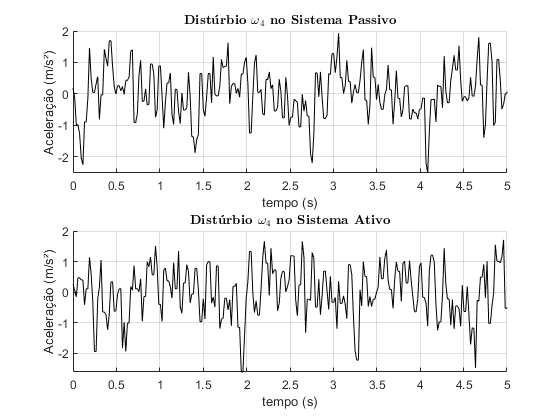


figure
subplot(211)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW4NoU*Ts, aceleracaoW4NoU,'k');
title("\textbf{Dist\'urbio $\omega_{4}$ no Sistema Passivo}", 'Interpreter', 'latex');
xlim([0 5])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

subplot(212)
hold on
grid
xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tW4*Ts, aceleracaoW4,'k');
title("\textbf{Dist\'urbio $\omega_{4}$ no Sistema Ativo}", 'Interpreter', 'latex');
xlim([0 5])
% axis([10 12 -15 15])
% legend("Dist\'urbio senoidal 11.97V");
hold off

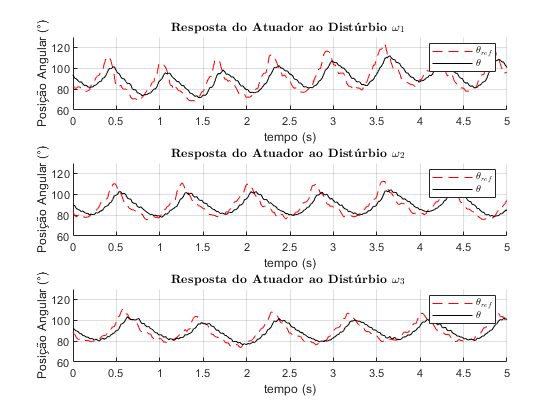

figure
subplot(311)
hold on
title("\textbf{Resposta do Atuador ao Dist\'urbio $\omega_{1}$ }", 'Interpreter', 'latex');
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tW1*Ts, W1U,'r--');
plot(tW1*Ts, W1Theta,'k');
legend("$\theta_{ref}$", "$\theta$", 'Interpreter', 'latex')
axis([0 5 60 130])
grid
hold off

subplot(312)
hold on
title("\textbf{Resposta do Atuador ao Dist\'urbio $\omega_{2}$ }", 'Interpreter', 'latex');
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tW2*Ts, W2U,'r--');
plot(tW2*Ts, W2Theta,'k');
legend("$\theta_{ref}$", "$\theta$", 'Interpreter', 'latex')
axis([0 5 60 130])
grid
hold off

subplot(313)
hold on
title("\textbf{Resposta do Atuador ao Dist\'urbio $\omega_{3}$ }", 'Interpreter', 'latex');
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tW3*Ts, W3U,'r--');
plot(tW3*Ts, W3Theta,'k');
legend("$\theta_{ref}$", "$\theta$", 'Interpreter', 'latex')
axis([0 5 60 130])
grid
hold off